# Używanie funkcji

Język Matlab zawiera bardzo wiele funkcji wspomagających pracę inżynierów i naukowców. Każda funkcja posiada swój zestaw argumentów i zwracanych wartości. Aby możliwe było użycie danej funkcji użytkownik musi przekazać do niej wszystkie wymagane argumenty.

Funkcje realizują różne zadania. Poniżej przedstawiono przykłąd użycia [funkcji obliczajacej sumę](https://www.mathworks.com/help/matlab/ref/sum.html) liczb w wektorze.

x = [[1,2,3];[4,5,6]];
suma = sum(x)

suma =      5     7     9


Wiele funkcji może pobierać dodatkowe argumenty. Na przykład funkcja [sum()](https://www.mathworks.com/help/matlab/ref/sum.html) wymaga jednego argumentu w postaci tablicy liczb. Dodatkowe argumenty mogą definiować czy suma obliczana jest dla całej tablicy czy dla kolumn lub wierszy.

sum(x,1)

ans =      5     7     9


sum(x,2)

ans =      6
    15


Przydatność takich środowisk jak Matlab wynika z faktu, że oferują one specjalistyczne funkcje dedykowane do konkretnych zadań, które bardzo przyspieszają pracę związaną z obliczeniami. Poniżej przykład utworzenia zmiennej losowej o rozkłądzie normalnym (Gaussa) i wygenerowanie tysiąca liczb pochodzących z tego rozkładu, a następnie wykonanie histogramu otrzymanych liczb. Dzięki temu, że funkcjonalności te są zamknięte w funkcjach, wykonanie takich obliczeń i ich wizualizacji zajmuje jedynie trzy linijki kodu.

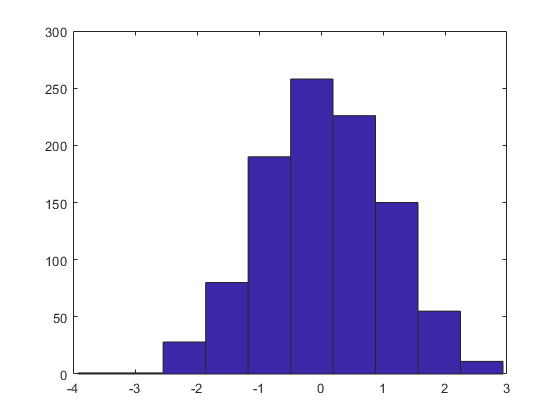

rozklad_gaussa = gmdistribution(0,1);
z = random(rozklad_gaussa,1000);
hist(z)